plot(score)
hold on
x = 1:960;
y(x) = 0.05;
plot(y)
output = score > 0.05;
hold off
confusionchart(label,double(output))
tp = 766,fp = 38, fn=34, tn = 122;

tp = 766

fp = 38

fn = 34

Prcision = tp/(tp+fp)

Prcision = 0.9527

Recall = tp/(tp+fn)

Recall = 0.9575

Accuracy= (tp+tn)/960

Accuracy = 0.9250

f1_score = 2*tp/(2*tp+fp+fn)

f1_score = 0.9551

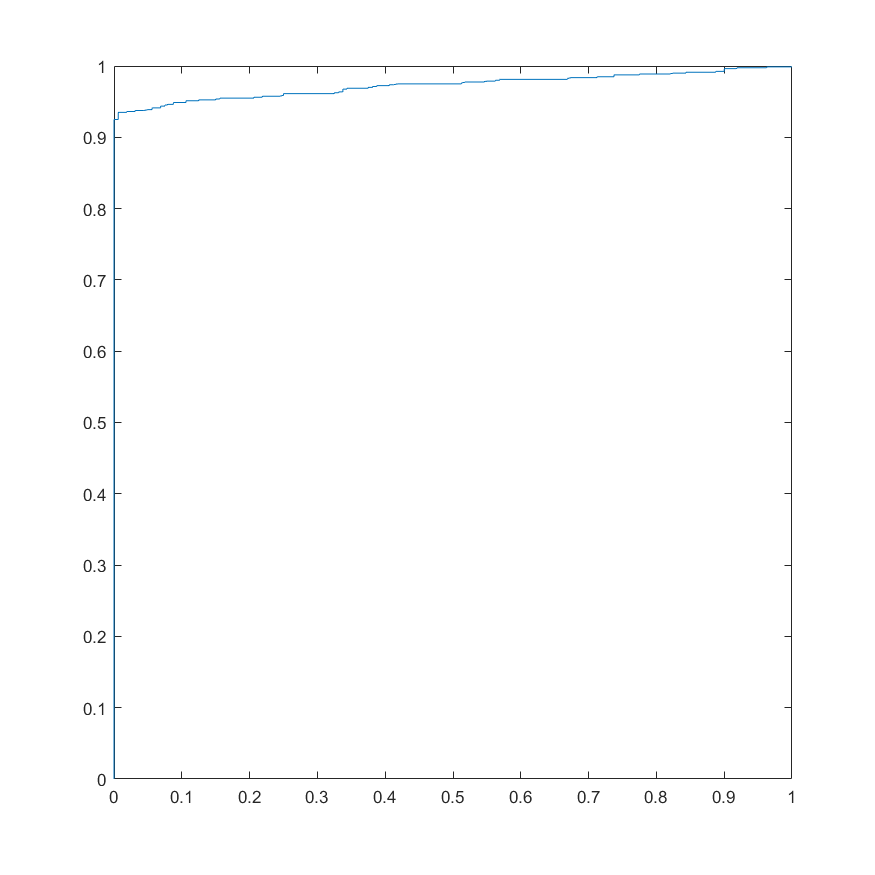

[tpr,fpr,thresholds] = roc(label,score);
plot(fpr,tpr)

AUC = trapz(fpr,tpr)

AUC = 0.9729